# 获取数据

clear %清除数据空间
clc %清除命令行
addpath(genpath(pwd)) %将当前目录及子目录加入MATLAB工作目录，否则无法调用函数
d_Data = get_hist_data('600519','d'); %获取茅台日度股票数据，该函数可以获取各种股票数据及指数数据
head(d_Data) %显示数据前几行

ans = 8×7 table
         date             open            high           close            low            volume       price_change
    ______________    ____________    ____________    ____________    ____________    ____________    ____________

    {'2021-07-09'}    {'1964.520'}    {'1985.910'}    {'1972.110'}    {'1945.000'}    {'30907.90'}    {'-12.890'} 
    {'2021-07-08'}    {'2000.100'}    {'2004.000'}    {'1985.000'}    {'1968.000'}    {'35516.69'}    {'-19.000'} 
    {'2021-07-07'}    {'2010.000'}    {'2028.880'}    {'2004.000'}    {'1999.010'}    {'28122.12'}    {'-8.900' } 
    {'2021-07-06'}    {'1995.000'}    {'2014.000'}    {'2012.900'}    {'1960.010'}    {'35282.51'}    {'18.900' } 
    {'2021-07-05'}    {'2000.000'}    {'2019.880'}    {'1994.000'}    {'1985.000'}    {'34420.95'}    {'-19.000'} 
    {'2021-07-02'}    {'2075.000'}    {'2075.000'}    {'2013.000'}    {'2011.500'}    {'46275.31'}    {'-92.000'} 
    {'2021-07-01'}    {'2059.970'}    {'2110.000'}    {'2105.00

# 数据处理

CloseP = str2num(char(d_Data.close));  %使用收盘价,其中str2num与char用于数据类型的转化
Rtrn = (CloseP(2:end,:) - CloseP(1:end-1,:))./CloseP(1:end-1,:);  %取简单收益率
Loss = -Rtrn; %损失为收入取相反数
%histogram(Loss);

# 对价格时间序列建模

## 数据处理

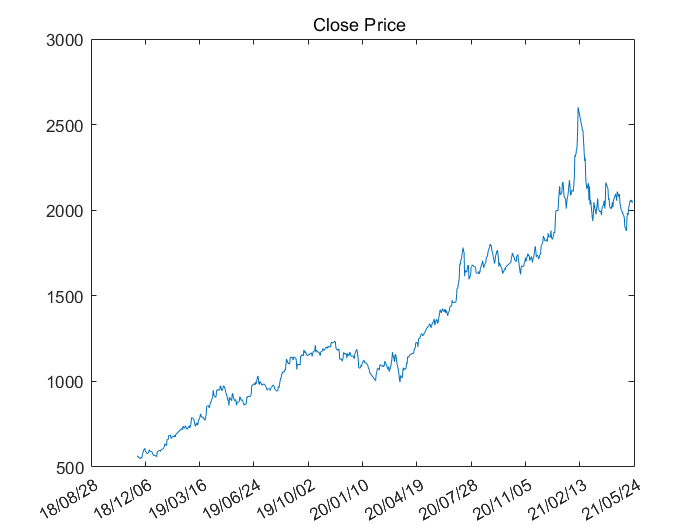

DateNumber = datenum(d_Data.date); %转换日期数据
figure %新建画布
plot(flipud(DateNumber),flipud(CloseP));%绘制价格时间序列
dateaxis('x',17);%转化横坐标为相应的日期格式
title('Close Price ') %图像的标题

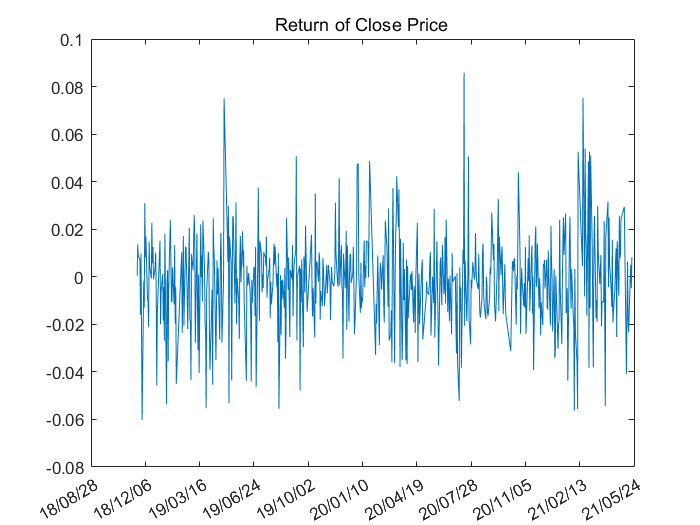

clf;figure %清除画布
plot(flipud(DateNumber(2:end,:)),flipud(Rtrn));%绘制价格时间序列
dateaxis('x',17);%转化横坐标为相应的日期格式
title('Return of Close Price')

## 平稳性检验

y_h_adf = adftest(Rtrn) %adf为自相关函数检验

y_h_adf = logical
   1


y_h_kpss = kpsstest(Rtrn)

y_h_kpss = logical
   0


通过检验，序列平稳

##  ACF和PACF 

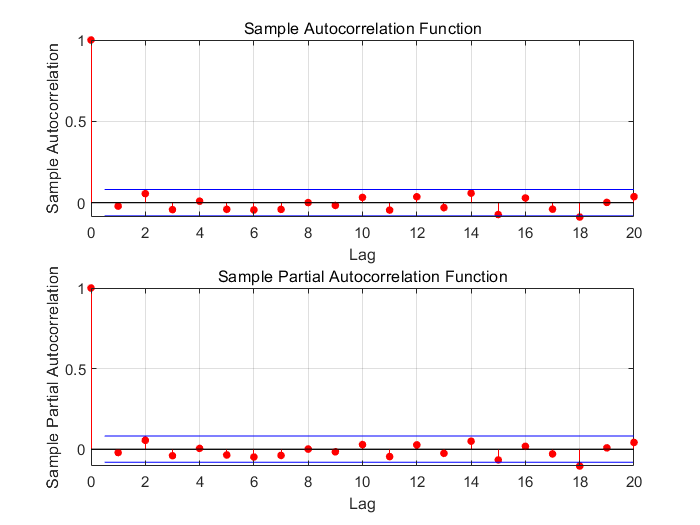

clf
subplot(211),autocorr(Rtrn); %分网格绘图，211表示2个图中的第一个
subplot(212),parcorr(Rtrn);

## `通过AIC，BIC等准则暴力选定阶数`

max_ar = 3;
max_ma = 3;
[AR_Order,MA_Order] = ARMA_Order_Select(Rtrn,max_ar,max_ma,1) %自动确定阶数

AR_Order = 1

MA_Order = 2

## 建立ARMA模型

Mdl = arima(AR_Order, 0, MA_Order); %建立模型，arima是内设函数
EstMdl = estimate(Mdl,Rtrn); %估计参数，estimate 为内设

 
    ARIMA(1,0,2) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant    -0.0035901      0.0015252       -2.3539         0.018579
    AR{1}         -0.87581        0.11189       -7.8274       4.9813e-15
    MA{1}          0.85937        0.11807        7.2786       3.3724e-13
    MA{2}         0.022384       0.042717         0.524          0.60028
    Variance    0.00038905     1.7503e-05        22.228      1.8231e-109



[res,~,logL] = infer(EstMdl,Rtrn);   %res即残差

## 模型检验

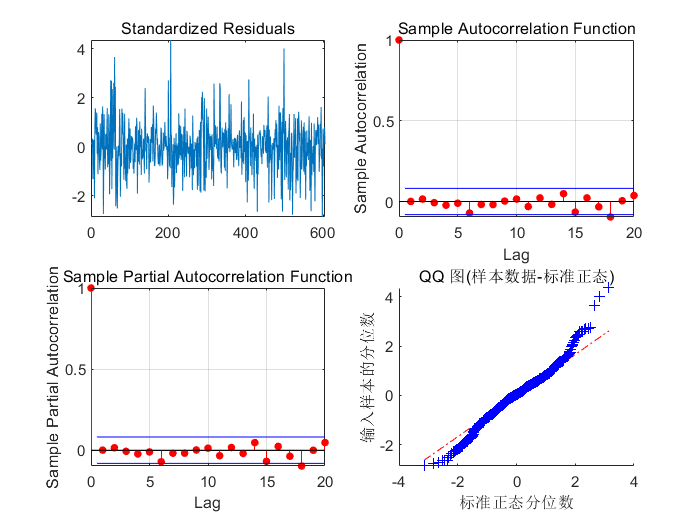

stdr = res/sqrt(EstMdl.Variance); %计算标准差
figure('Name','残差检验')
subplot(2,2,1)
plot(stdr)
title('Standardized Residuals')
subplot(2,2,2) %分窗口绘图
autocorr(stdr) %自相关系数
subplot(2,2,3)
parcorr(stdr) 
subplot(2,2,4)
qqplot(stdr) %qq图

## 向前预测

step = 5; %预测步数为50
[forData,YMSE] = forecast(EstMdl,step,'Y0',Rtrn) %forcast内设函数，向前预测

forData =    -0.0018
   -0.0020
   -0.0018
   -0.0020
   -0.0019


YMSE = 	1.0e+-3 *

    0.3891
    0.3892
    0.3897
    0.3901
    0.3904


# 窗口滚动计算Weight of VaR

## 计算历史数据的VaR

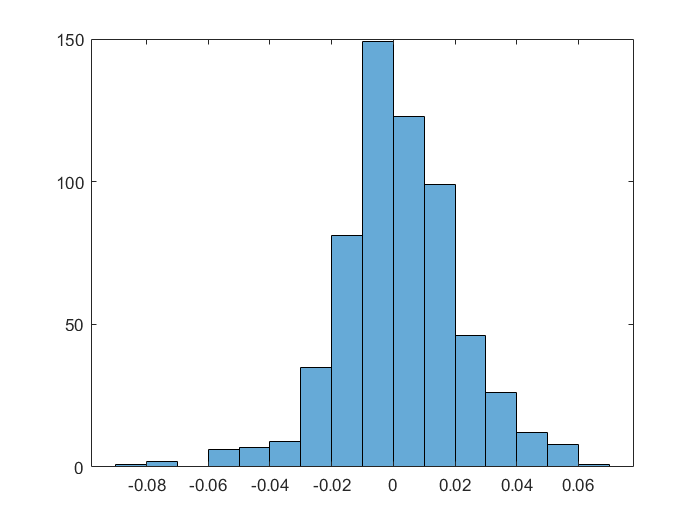

Loss = -Rtrn; %损失为收入取相反数
clf;figure
histogram(Loss);

[VaR,Expected_shortall] = Weight_of_VaR(Loss,0.8)

n = 605

VaR = 0.0231

Expected_shortall = 2.7627

## 向前滚动五步做预测

for i = 1:length(forData)
    [VaR,Expected_shortall] = Weight_of_VaR([Loss;-forData(1:i,:)],0.8)
end

n = 606

VaR = 0.0231

Expected_shortall = 2.7627

n = 607

VaR = 0.0231

Expected_shortall = 2.7627

n = 608

VaR = 0.0231

Expected_shortall = 2.7627

n = 609

VaR = 0.0231

Expected_shortall = 2.7627

n = 610

VaR = 0.0231

Expected_shortall = 2.7627